# MCIR User's Guide

Kerry S. Martin, [martin@wild-wood.net](mailto:martin@wild-wood.net)

*February 21, 2021*

## Introduction

MCIR is a set of Matlab classes and functions that allows the user to create and analyze a linear, lumped, time-invariant (LLTI) electronic circuit. Any LLTI electronic device, as well as a circuit comprised of LLTI devices, may be described by a set of dynamic and static equations of the form:


$$\begin{array}{rcl}
0 &=& P_{11} \dot{x}+P_{12} v+P_{13\;} u\\
0&=&P_{21} x+P_{22} v+P_{23} u\\
y&=&P_{31} x+P_{32} v+P_{33} u
\end{array}$$


Through manipulation, these equations may be arranged into a state-space system of the form:


$$\begin{array}{rcl}
\dot{x} &=& A x \;+\;B u\\
y&=&C x \;+\;D u
\end{array}$$


## Creating a Circuit

Start by importing the MCIR library:

import MCIR.*

Create a new Circuit object using the **Circuit constructor**, assigning a name during creation:

CIR = Circuit("Example 0");

The name can also be changed after creating the Circuit object, by assigning to the **name** property:

CIR.name = "Example 1";

By itself, a Circuit has few properties:

CIR

CIR =   Circuit with properties:

    circuit_name: "Example 1"
      components: 0


Add devices are added to the Circuit using the **add** method. Build a simple RC circuit in this way:

CIR.add("V1 1 0 DC(10)")
CIR.add("R1 1 2 1k")
CIR.add("C1 2 0 1u IC=5")
CIR.add("I1 2 0 0")
CIR.add("O1 V(2)")

Devices in the circuit may be altered using the **alter** method, or removed using the **remove** method. The circuit may be cleared entirely using the **clear** method, but that will not be demonstrated here.

CIR.alter("R1", "10k")
CIR.remove("I1")

The Circuit may be listed using the **list** method:

CIR.list

* Example 1
V1 1 0 DC=10
R1 1 2 10k
C1 2 0 1u IC=5
O1 V(2)


## Analyzing the Circuit

The Circuit is represented by a set of differential equations. Use the **equations** method to view these:

EQN = CIR.equations

EQN = struct with fields:
    name: "Example 1"
       P: [7×7 double]
       x: [1×1 struct]
       v: [1×5 struct]
       u: [1×1 struct]
       y: [1×1 struct]


EQN.P

ans =     0.0000         0         0         0         0   -1.0000         0
         0    0.0001         0    1.0000   -0.0001         0         0
         0         0         0   -1.0000         0   -1.0000         0
         0   -1.0000    1.0000         0         0         0   10.0000
         0   -0.0001         0         0    0.0001    1.0000         0
    1.0000         0    1.0000         0   -1.0000         0         0
         0         0         0         0    1.0000         0         0


The state-space representation for the Circuit may be obtained using the **ss** method:

[SYS,x0] = CIR.ss

SYS =
 
  A = 
           VC(C1)
   VC(C1)    -100
 
  B = 
             DC
   VC(C1)  1000
 
  C = 
         VC(C1)
   V(2)       1
 
  D = 
         DC
   V(2)   0
 
Continuous-time state-space model.



x0 = 5

This state-space model may be analyzed using Matlab commands, or the circuit may be directly analyzed using analysis commands in the MCIR library.

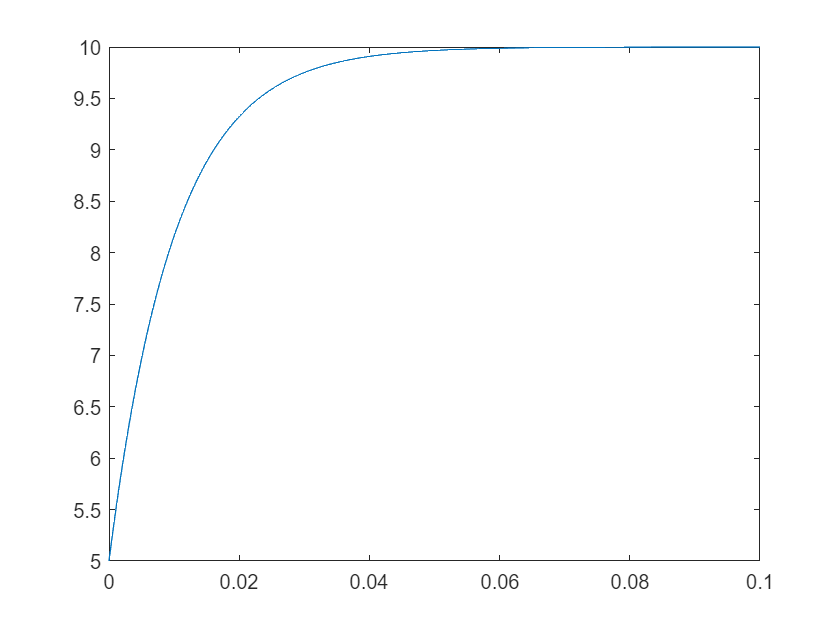

N = 1001;
Tend = 0.1;
t = linspace(0,Tend,N);
u = ones(1,N);
y = lsim(SYS,u,t,x0);
plot(t,y)